Load images

%directory in which files are stored, Change if the path differs
Dir = "data_fruit/";

% list all png files in the AllImages variable
AllImages = dir(fullfile(Dir,"*.png"));

% number of images
num_images = length(AllImages);
%vector to store the images
I = zeros([19200 , num_images],"double"); 

for i = 1:num_images    % get the name of ith image
    image = fullfile(Dir,AllImages(i).name);
    %read the ith image
    im = imread(image);
    %reshape the image into a single vector and append it into the I matrix
    % while reshaping, the image is reshaped into a column vector    
    I(:,i) = reshape(im,[19200, 1]); 
end
% I contains each image as a column.

## PCA

me = (sum(I,2)/size(I,2)); %mean
I = I - me; %origin shifted to mean
%calculate the covariance matrix. Note that the covariance matrix for distribution is estimated using its MLE estimate
co = I*I' / size(I,2);

[u, s] = eigs(co,4); % u=eigen vectors, diag(s)= eigenvalues. Since we need only 4 maximum eigen values, we use eigs(co,4)

Show the images of mean and the eigenvectors

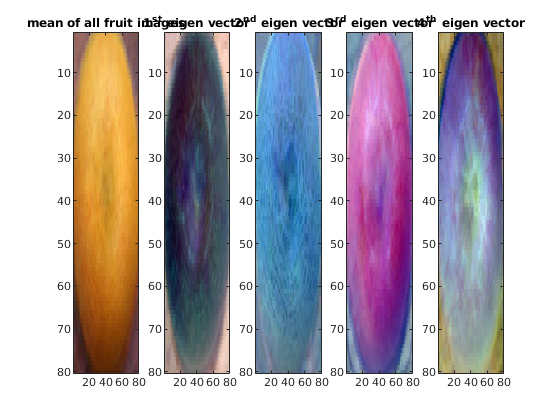

figure
subplot(1,5,1),imagesc(rescale(reshape(me,[80, 80, 3])))
title("mean of all fruit images")
subplot(1,5,2), imagesc(rescale(reshape(u(:,1),[80, 80, 3])))
title("1^{st} eigen vector")
subplot(1,5,3), imagesc(rescale(reshape(u(:,2),[80, 80, 3])))
title("2^{nd} eigen vector")
subplot(1,5,4), imagesc(rescale(reshape(u(:,3),[80, 80, 3])))
title("3^{rd} eigen vector")
subplot(1,5,5), imagesc(rescale(reshape(u(:,4),[80, 80, 3])))
title("4^{th} eigen vector")

Plot of first ten eigen-values

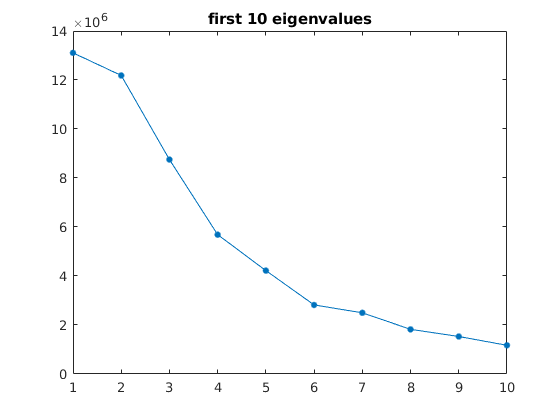

D = eigs(co,10); %calculate the first 10 eigen values
figure %plot 
plot(D,"Marker",".","MarkerSize",15)
title("first 10 eigenvalues")

## Projections

The closest representation will be the projection of the image on the vector space formed by the four eigen vectors as proved in the report

weights = u' * I; % dot product of the image on the smaller space
re_I = u*weights+me; %the reconstruction is simply weights * eigen_vector + mean.

Plotting the reconstructed images and original images

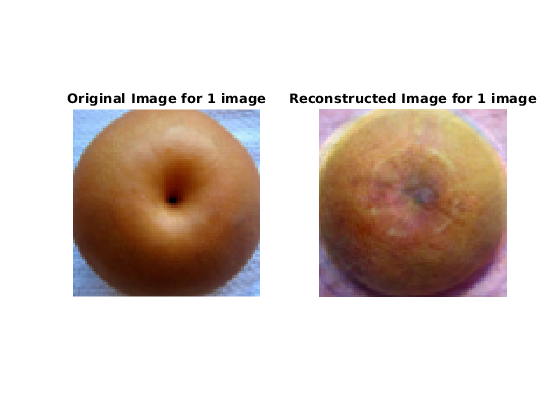

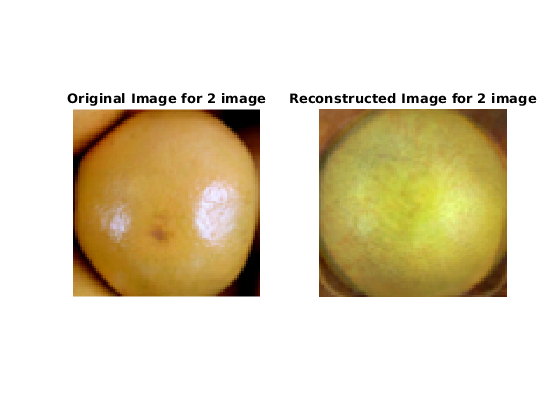

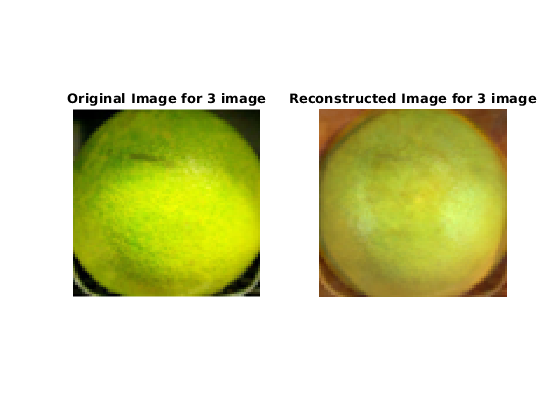

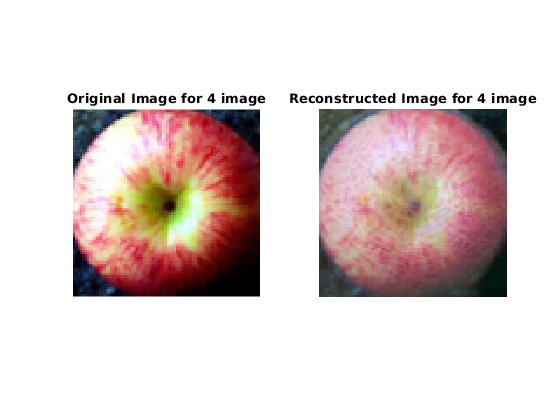

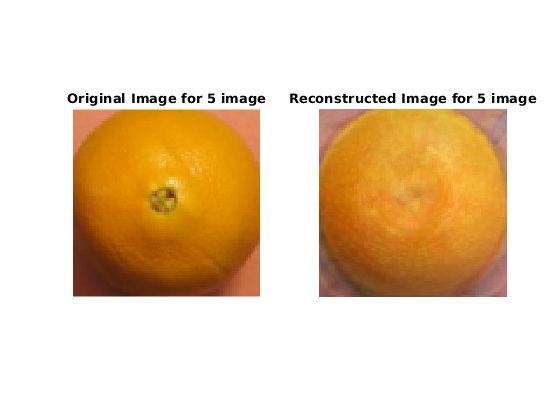

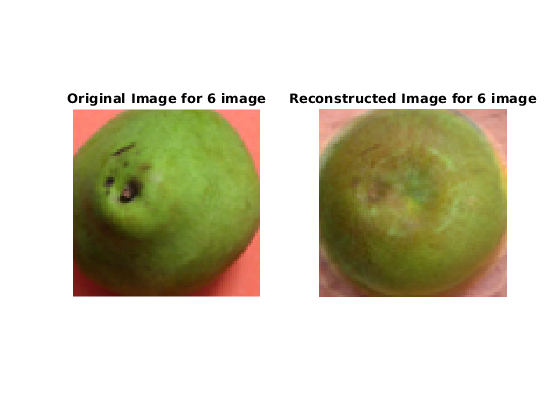

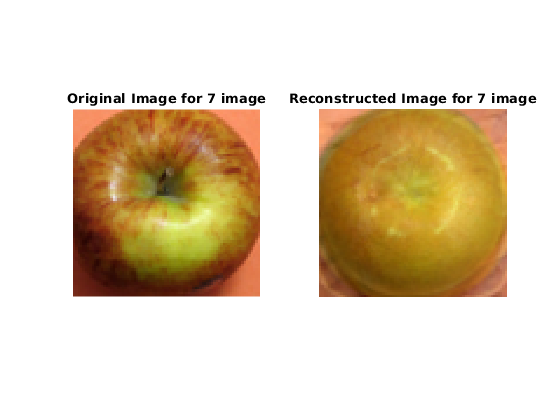

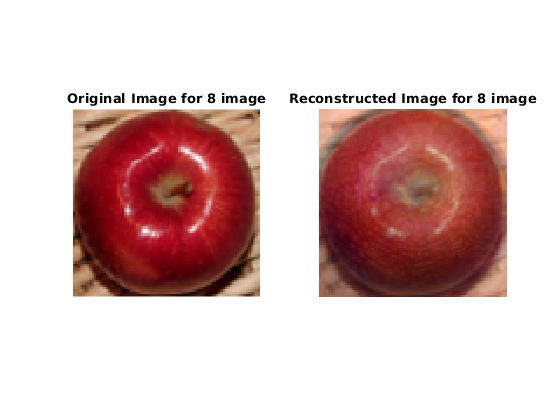

for i=1:num_images
    figure
    subplot(1,2,1), imshow(rescale(reshape(I(:,i)+me,[80, 80,3]))) %original image, We subtracted mean so have to add back
    title("Original Image for "+num2str(i) + " image")
    subplot(1,2,2), imshow(rescale(reshape(re_I(:,i),[80, 80,3]))) %the reconstructed images
    title("Reconstructed Image for "+num2str(i) + " image")
end

Random Fruits from normal distribution

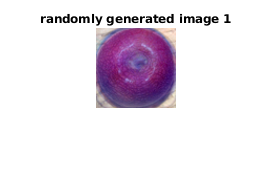

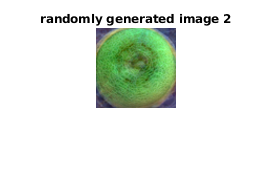

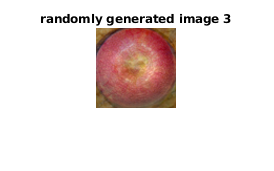

%seed the random number generator
rng(4)
for i=1:3
    % get weights for the four eigenvectors.
    %To notice difference, weights must be comparable to the norm of mean
    % So it is multiplied by the norm of mean
    % (randn + 0.1) is used to increase the scale a bit
    w = randn(4,1)*(rand+0.1)*norm(me);
    % construct the image of fruit from the weights
    new_image = u*w+me;
    %display the image
    figure, imshow(rescale(reshape(new_image,[80, 80,3]))) 
    title("randomly generated image "+num2str(i))
end